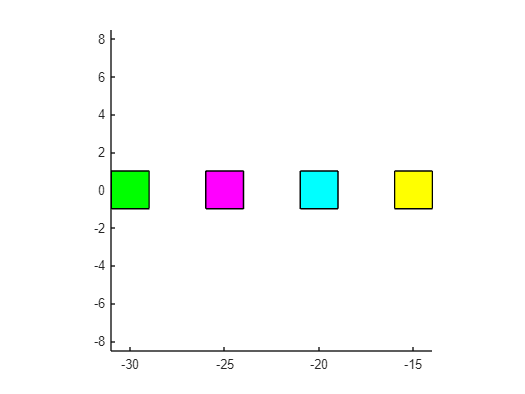

verticesCube1 = [
    -1, 1, 1, -1, -1, 1, 1, -1;
    -1, -1, 1, 1, -1, -1, 1, 1;
    -1, -1, -1, -1, 1, 1, 1, 1;
    1, 1, 1, 1, 1, 1, 1, 1
    ];

move1Cube = [
    1, 0, 0, 0;
    0, 1, 0, 5;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];

move2Cube = [
    1, 0, 0, 0;
    0, 1, 0, 10;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];

move3Cube = [
    1, 0, 0, 0;
    0, 1, 0, 15;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];

verticesCube2 = move1Cube * verticesCube1;
verticesCube3 = move2Cube * verticesCube1;
verticesCube4 = move3Cube * verticesCube1;

facesCube = [
    1, 2, 6, 5;
    2, 3, 7, 6;
    3, 4, 8, 7;
    4, 1, 5, 8;
    1, 2, 3, 4;
    5, 6, 7, 8
    ];

moveCamera = [
    1, 0, 0, 0;
    0, 1, 0, 15;
    0, 0, 1, 0;
    0, 0, 0, 1;
]; 

phi = 0;
teta = pi/3;
phi1 = pi;

rotateYMatrix = [
    cos(teta), 0, sin(teta), 0;
    0, 1, 0, 0;
    -sin(teta), 0, cos(teta), 0;
    0, 0, 0, 1
    ];

rotateZMatrix = [
    cos(phi), -sin(phi), 0, 0;
    sin(phi), cos(phi), 0, 0;
    0, 0, 1, 0;
    0, 0, 0, 1
    ];
rotateXMatrix = [
    1, 0, 0, 0;
    0, cos(phi1), -sin(phi1), 0;
    0, sin(phi1), cos(phi1), 0;
    0, 0, 0, 1
    ];

nverticesCube1 = (rotateZMatrix * rotateXMatrix)^(-1) * moveCamera * verticesCube1;
nverticesCube2 = (rotateZMatrix * rotateXMatrix)^(-1) * moveCamera * verticesCube2;
nverticesCube3 = (rotateZMatrix * rotateXMatrix)^(-1) * moveCamera * verticesCube3;
nverticesCube4 = (rotateZMatrix * rotateXMatrix)^(-1) * moveCamera * verticesCube4;
DrawShape (nverticesCube1, facesCube, 'y')
DrawShape (nverticesCube2, facesCube, 'c')
DrawShape (nverticesCube3, facesCube, 'm')
DrawShape (nverticesCube4, facesCube, 'g')
axis equal;
view(90, 0);

%view(3);


function DrawShape(vertices, faces, color)
    patch('Vertices', (vertices(1:3,:)./vertices(4,:))','Faces', faces, 'FaceColor', color);

end